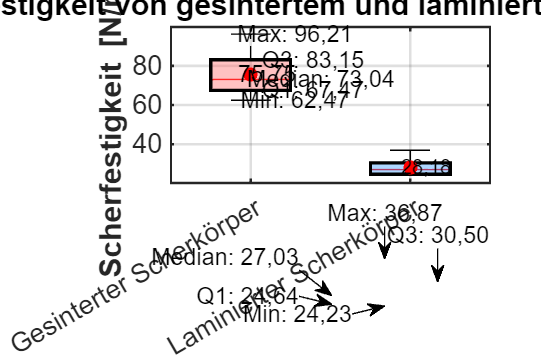

data1 = [62.47, 86.81, 79.48, 72.66, 96.21, 67.83, 73.42, 67.10];
data2 = [36.87, 27.09, 24.46, 26.97, 24.23, 27.82, 24.83, 33.19];

data = [data1(:), data2(:)];
positions = [1, 3]; 

figure('Position', [100, 100, 900, 600]); 
boxplot(data, 'Positions', positions, 'Widths', 1, 'Labels', {'Gesinterter Scherkörper', 'Laminierter Scherkörper'}, 'Symbol', 'k+');

hold on;

h = findobj(gca, 'Tag', 'Box');
colors = [0.2 0.6 1; 1 0.4 0.4]; 
for j = 1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(j, :), 'FaceAlpha', 0.4, 'EdgeColor', 'k', 'LineWidth', 2);
end

stats1 = quantile(data1, [0, 0.25, 0.5, 0.75, 1]); 
stats2 = quantile(data2, [0, 0.25, 0.5, 0.75, 1]);
mean1 = mean(data1);
mean2 = mean(data2);

plot(positions(1), mean1, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
plot(positions(2), mean2, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);

% Format numbers with commas
formatNumber = @(x) strrep(sprintf('%.2f', x), '.', ',');

text(positions(1)+0.2, mean1 , formatNumber(mean1), 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.55, stats1(1) , ['Min: ', formatNumber(stats1(1))], 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.78, stats1(2), ['Q1: ', formatNumber(stats1(2))], 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.88, stats1(3), ['Median: ', formatNumber(stats1(3))], 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.78, stats1(4), ['Q3: ', formatNumber(stats1(4))], 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.55, stats1(5), ['Max: ', formatNumber(stats1(5))], 'FontSize', 14, 'Color', 'black', 'HorizontalAlignment', 'center');

text(positions(1)+2.2, mean2 , formatNumber(mean2), 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
annotation('textarrow', [0.651 0.711], [0.128 0.15], 'String', ['Min: ', formatNumber(stats2(1))], 'FontSize', 14, 'Color', 'black');
annotation('textarrow', [0.553 0.613], [0.177 0.155], 'String', ['Q1: ', formatNumber(stats2(2))], 'FontSize', 14, 'Color', 'black');
annotation('textarrow', [0.553 0.613], [0.25 0.179], 'String', ['Median: ', formatNumber(stats2(3))], 'FontSize', 14, 'Color', 'black');
annotation('textarrow', [0.809 0.809], [0.31 0.217], 'String', ['Q3: ', formatNumber(stats2(4))], 'FontSize', 14, 'Color', 'black');
annotation('textarrow', [0.711 0.711], [0.371 0.281], 'String', ['Max: ', formatNumber(stats2(5))], 'FontSize', 14, 'Color', 'black');

set(gca, 'FontSize', 16, 'LineWidth', 1.5);
ylabel('Scherfestigkeit [N/mm^2]', 'FontSize', 18, 'FontWeight', 'bold', 'Position', [-0.5, mean(get(gca, 'YLim'))]); 
title('Scherfestigkeit von gesintertem und laminiertem Scherkörper', 'FontSize', 18, 'FontWeight', 'bold', 'Position', [2, max(get(gca, 'YLim')) + 2.5]); 
grid on;
hold off;

print -depsc boxplot_final.eps